# Separating Overlapping Bison in a Mask

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

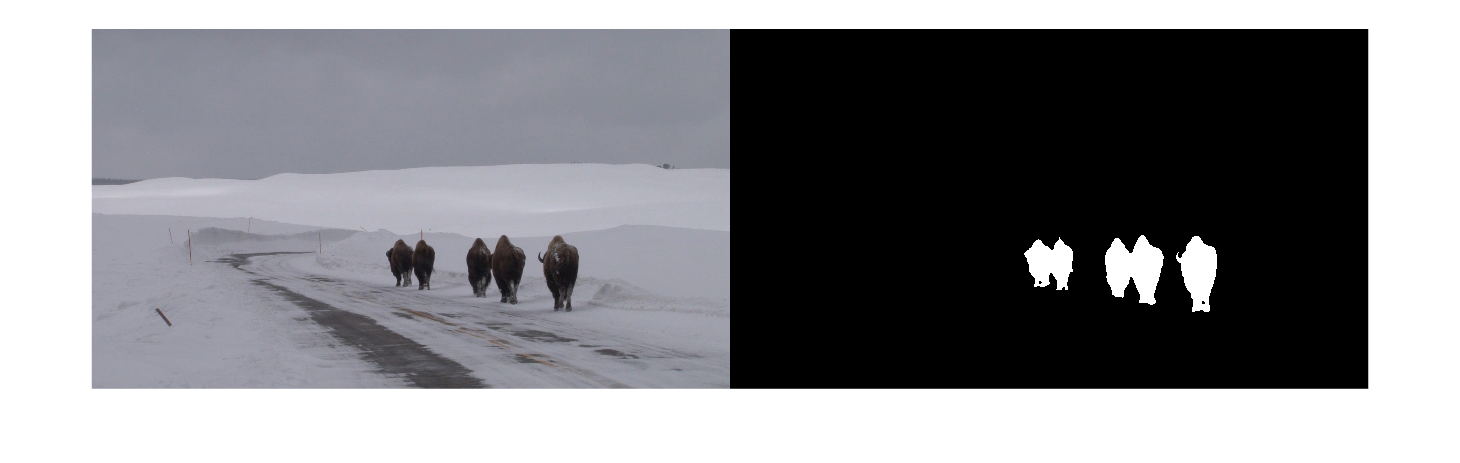

bison = imread("./images/bison.jpg");

bisonBW = bisonMask(bison);  % local function at bottom of script
imshowpair(bison, bisonBW, "montage")

## Task 1

To apply watershed, you need a grayscale image that approximately marks the bison.

You can often use a distance matrix for the grayscale image. In the distance matrix, each pixel is assigned a value that is the minimal distance between that pixel and the background.

You can use the `bwdist` function to calculate the distance matrix that assigns a value to each pixel that is the minimal distance between that pixel and the nearest non-zero pixel.

`D` `=` `bwdist``(``BW``)``;`

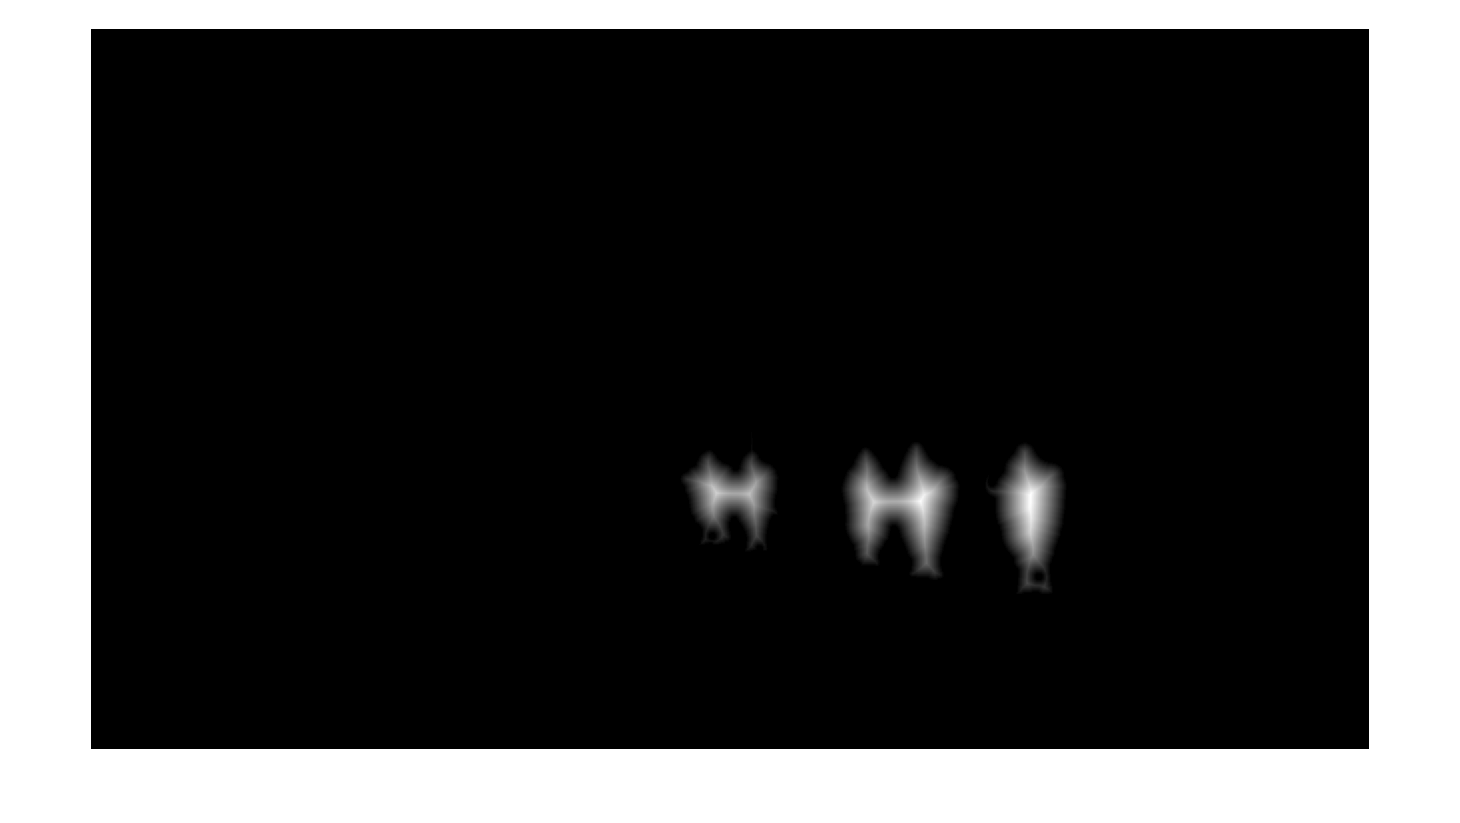

d = bwdist(~bisonBW);
imshow(d, [])

## Task 2

Since the background needs to be bright to apply watershed, you need to take the complement of the grayscale image.

`I2` `=` `imcomplement``(``I``)``;`

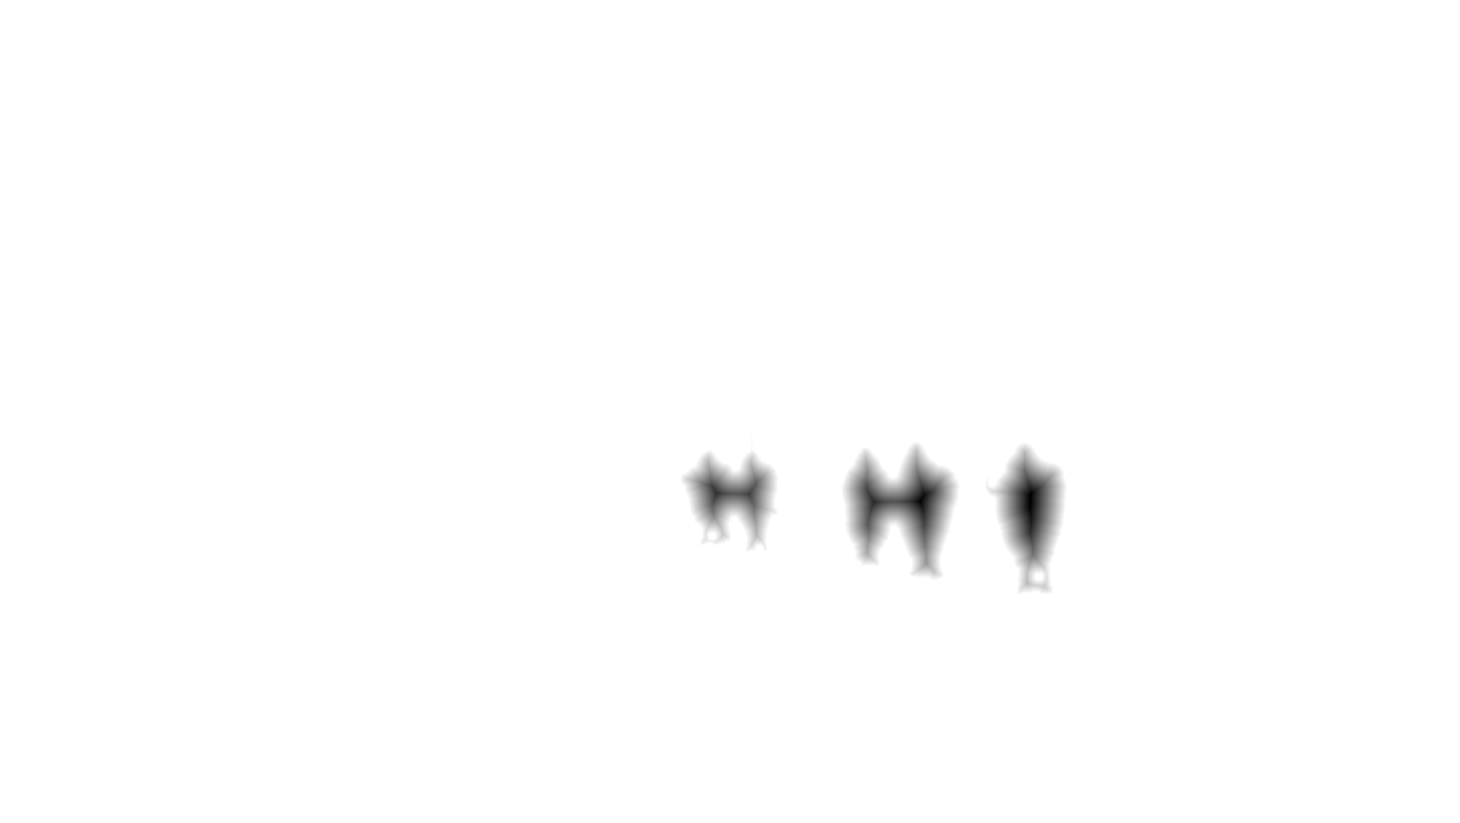

d = imcomplement(d);
imshow(d, [])

## Task 5

The bison weren't separated correctly. Watershed identified too many basins. You can suppress minima with depth less than `h` using `imhmin`.

`I2` `=` `imhmin``(``I``,``h``)``;`

d = imhmin(d, 3);

## Task 3

You can apply the watershed algorithm to a grayscale image using the `watershed` function.

`ws` `=` `watershed``(``gs``)``;`

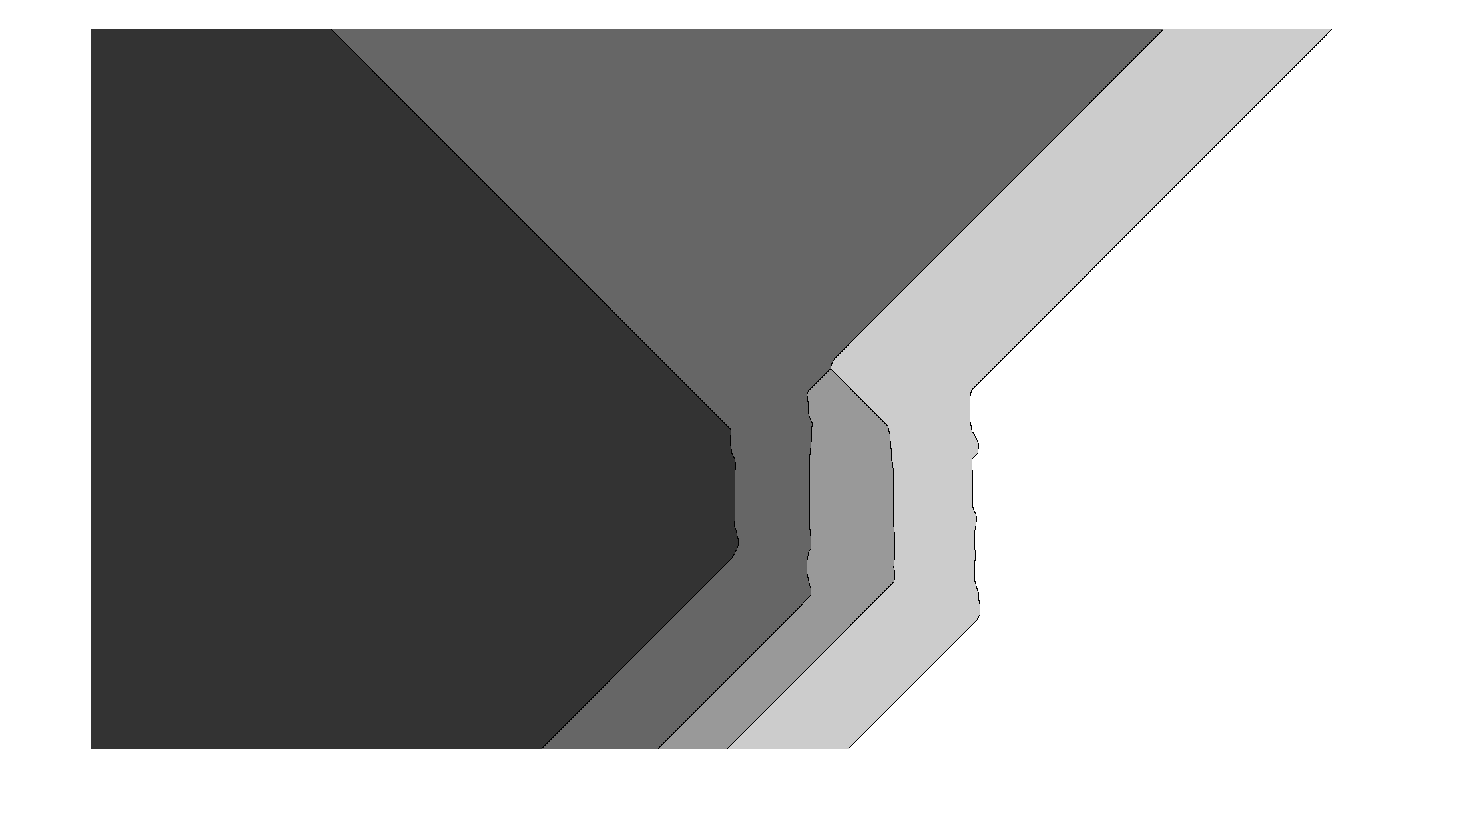

bisonSep = watershed(d);
imshow(bisonSep, [])

## Task 4

You can use a mask to assign background pixels to be a certain value. The following code changes every pixel of `im` to `5` where `BW` is `true`.

`im``(``BW``)` `=` `5`

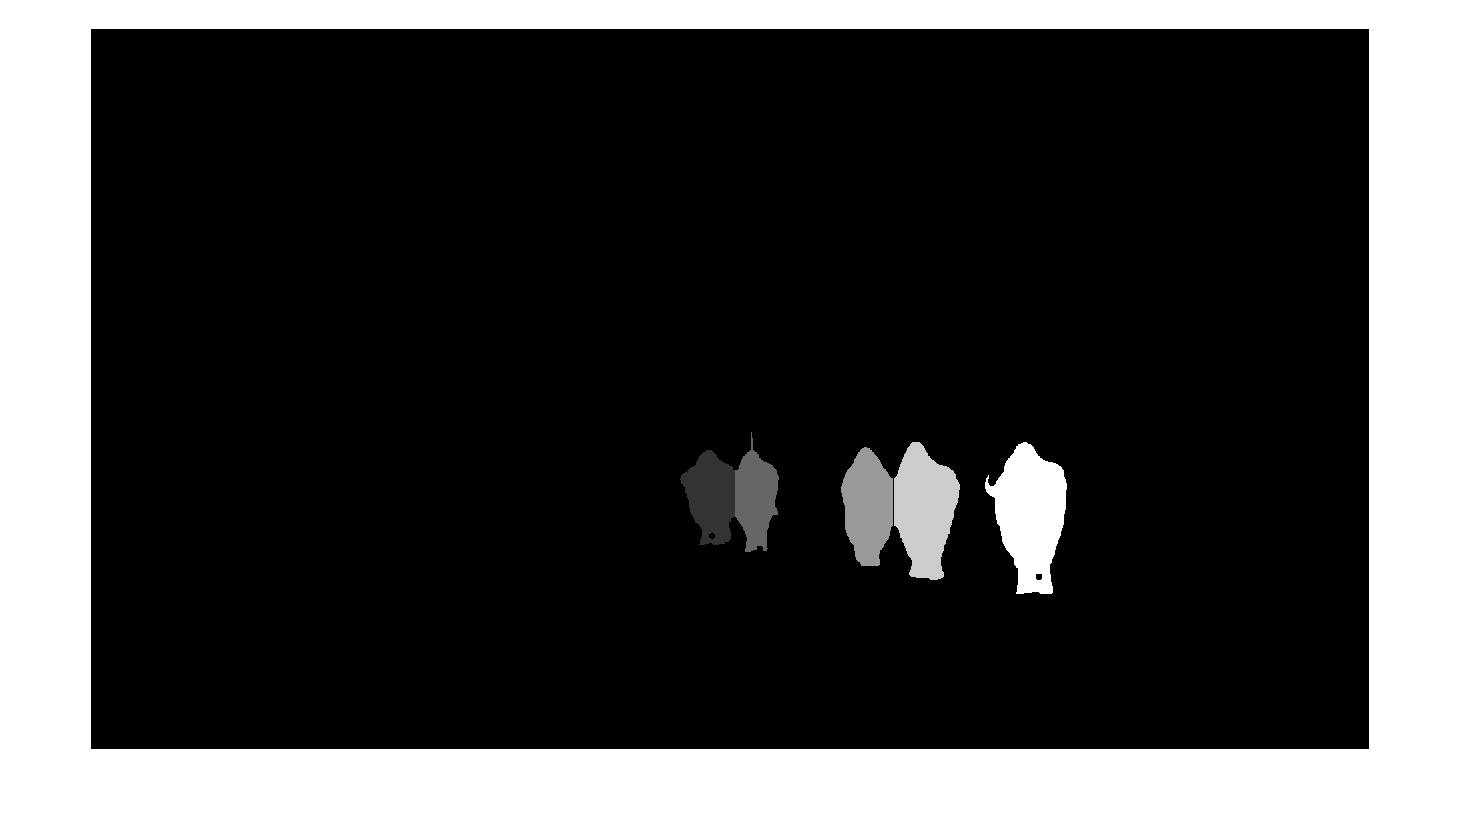

bisonSep(~bisonBW) = 0;
imshow(bisonSep, [])

## Task 6

You can use `labeloverlay` with the label matrix you created from watershed to view the separated segmentation in context.

`I2` `=` `labeloverlay``(``im``,``labelMat``)``;`

The output is a new image that you can view with `imshow`.

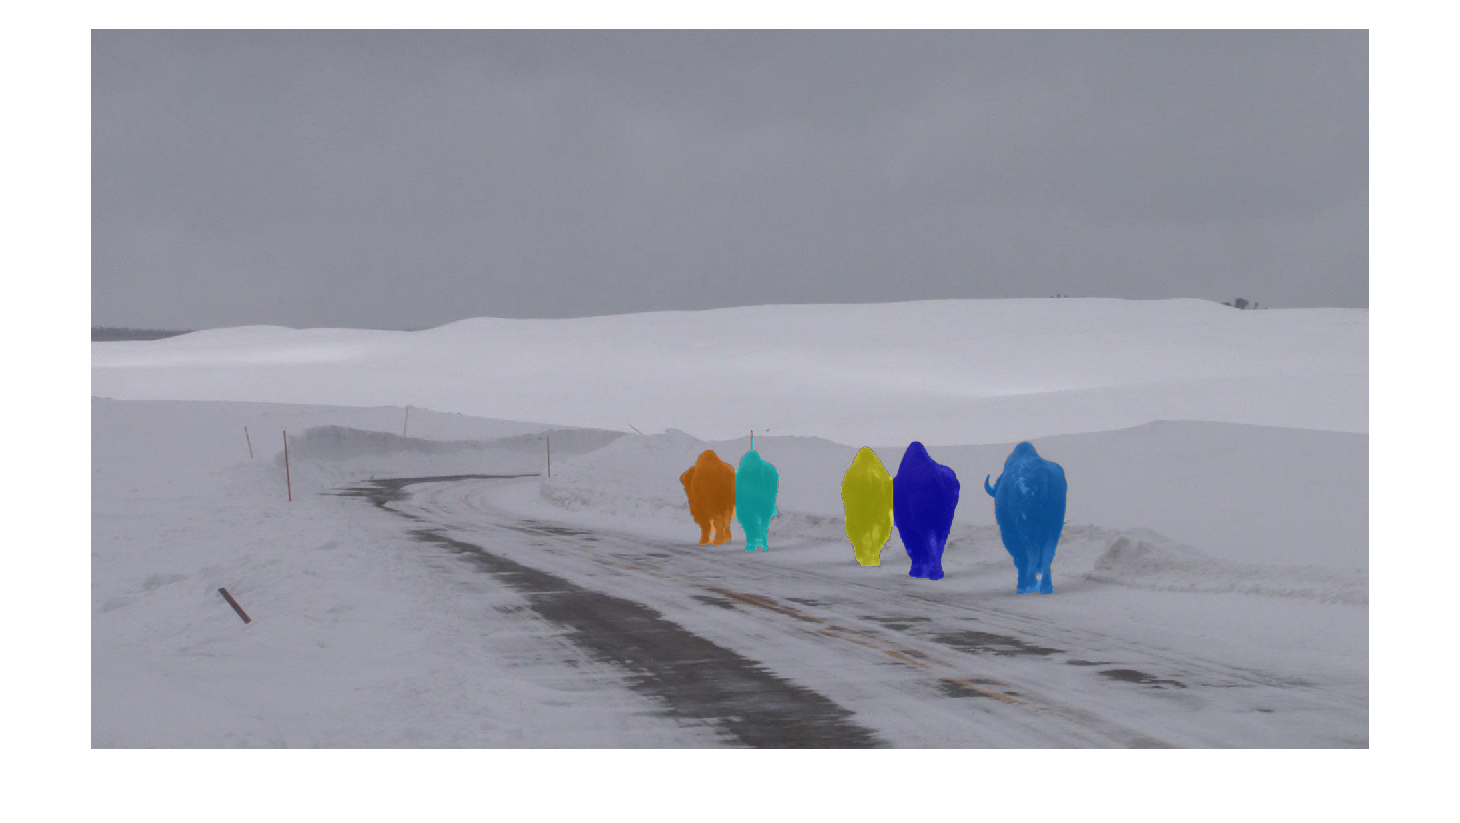

bisonOverlay = labeloverlay(bison, bisonSep);
imshow(bisonOverlay)

function mask = bisonMask(bison)
    gray = rgb2gray(bison);
    bisonBW = gray < 65;
    
    bisonBW = bwareaopen(bisonBW, 150);
    
    mask = activecontour(bison, bisonBW, "Chan-Vese", "ContractionBias", -.25);
    
    se = strel("disk", 5);
    mask = imclose(mask, se);
end